# 13 Linear Programming: The Simplex Method

The **standard form **of a linear program is


$$\left.\begin{array}{lll}\min & c^T x\\ \text{subject to} & \\ & Ax =b \\ & x\geq 0\end{array}\qquad \right\} (LP)$$


- $c, x \in \mathbb{R}^n$, 

- $b \in \mathbb{R}^m$,

- $n$ number of variables, $m$ is the number of constraints.

- $A \in \mathbb{R}^{m\times n}$ ( We assum that $A$ has full rank and $m < n$)

% rng("default")
% A = randi([-3,4],4,4);
% A(4,:) = A(3,:);
% [Q,R,U] = qr(A);
% Q(:,1:3)*R(1:3,:);
% A*U;

**Other forms can be transformed into this form**

- $\min c^Tx, \text{ subject to } Ax \leq b$, we add *slack variables.*

- $\min c^Tx, \text{ subject to } Ax \geq b$, $x\geq 0$ we subtract *slack variables (add surplus).*

- $\min c^Tx, \text{ subject to } Ax = b, x\leq u$, we add *slack variables.*

The feasible set of (LP) is defined as 


$$\Omega =\{x\in \mathbb{R}^n | Ax=b, x\geq 0\}$$
 

- We say that the linear program (LP) is **infeasible** if the feasible set is empty. 

- If $\Omega = \emptyset$, (LP) has no solution

- $\Omega$ is a convex set.

- We say that the problem (LP) is **unbounded** if the objective function is unbounded below on the feasible region, that is, there is a sequence of points $x_ k$ feasible for (LP) such that $c^T x_k \downarrow  -\infty $. (Of course, unbounded problems have no solution).

- If (LP) is bounded and feasible, it can have one solution of infinitely many solution.

#### OPTIMALITY CONDITIONS 

The Lagrangian function of (LP) is 


$$\mathcal{L}(x,\lambda,s) = c^Tx - \lambda^T(Ax-b) - s^Tx$$


The first order optimality conditions, KKT, (Theorem 12.1)  gives that if $x^*$ is an optimal feasible solution to (LP), then there exist $\lambda \in \mathbb{R}^m$ and $s\in\mathbb{R}^n$ such that


$$\begin{array}{rll}A^T\lambda + s &=& c \\ Ax &=& b \\ x &\geq& 0 \\ s&\geq&0 \\ s_ix_i &=&0, i=1,\cdots n\end{array}$$


- These conditions are also necessary. 

- For a vector triple $(x^*, \lambda^*,s^*)$ that satisfy these conditions, we have $c^Tx^*=b^T\lambda^*$

- The feasible point $\bar{x}$ is optimal if and only if  $\bar{x}^T s^\ast  = 0$,

#### THE DUAL PROBLEM

The dual problem for (LP) is defined as 


$$\max b^T\lambda, \text{ subject to } A^T\lambda \leq c \quad (\text{DLP})$$


This can be rewritten as 


$$\max b^T\lambda, \text{ subject to } A^T\lambda + s = c, s\geq 0$$


- (LP) is called the primal problem

- The primal–dual relationship is symmetric

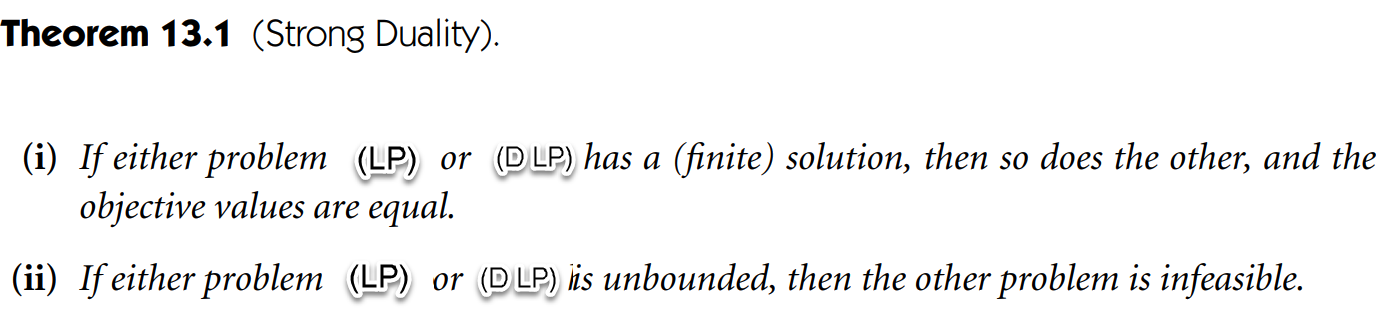

Remark

- The multiplier values λ and s indicate the sensitivity of the optimal objective value to perturbations in the constraints. In fact, the process of finding (λ,s) for a given optimal x is often called **sensitivity analysis**

#### 13.2 GEOMETRY OF THE FEASIBLE SET

**Definitions**

▶ A vector $x\in\mathbb{R}^n$ is called ***basic feasible point*** of (LP) if 

        1️⃣ it is feasible ($Ax=b, x\geq 0$) and 

        2️⃣ there is a subset $\mathfrak{B}$ of $\{1,2,\cdots,n\}$ such that

                a. $\mathfrak{B}$ contains exactly $m$ indices,

                b. $i\not\in\mathfrak{B}$ implies that $x_i=0$  (that is, the bound $x_i \ge  0$ can be inactive only if $i \in  \mathfrak{B}$);

                c. The $m\times m$ matrix $B$ defined by $B=[A_i]_{i\mathfrak{B}}$, ($A_i$ is the ith column of $A$) is nonsingular.

▶ A set $\mathfrak{B}$ satisfying the above is called **basis **for (LP)

▶ The matrix $B$ is called the **basis matrix.**

▶ A vector $x\in\mathbb{R}^n$ is called ***basic optimal point*** of (LP) if it is a solution of (LP) and also a basic  feasible point. 

▶ **(Degeneracy)**. A basis $\mathfrak{B}$ is said to be **degenerate** if $x_i=0$ for some $i \in  \mathfrak{B}$, where $x$ is the basic feasible solution corresponding to $\mathfrak{B}$. A linear program (LP) is said to be **degenerate** if it has at least one degenerate basis.

**Theorem 13.2 (***fundamental theorem of linear programming***)**

- If (LP) has a nonempty feasible region, then there is at least one basic feasible point; 

- If (LP) has solutions, then at least one such solution is a basic optimal point. 

- If (LP) is feasible and bounded, then it has an optimal solution.

#### VERTICES OF THE FEASIBLE POLYTOPE

- The feasible set defined by the linear constraints is a ***polytope***, and 

- the **vertices** of this polytope are the points that do not lie on a straight line between two other points in the set.

- Algebraically, the **vertices** are exactly the **basic feasible points** defined above.           

**Theorem 13.3. **

All basic feasible points for (LP) are vertices of the feasible polytope $\{x | Ax =b, x \ge  0\}$, and vice versa.